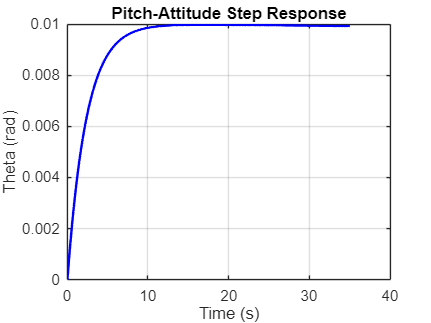

clear
clc


% 0 Controller value

Kp_1 = -99.9;

Kp_2 = 42;

Ki_2 = 0.031;

% 1 Run model
out = sim('Pitch_Attitude_Hold.slx');

% 2 Extract time and signal data
t = out.theta.Time;      % Time vector
theta = out.theta.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, theta, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Theta (rad)');
title('Pitch-Attitude Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(theta, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 5.0119
    TransientTime: 8.4797
     SettlingTime: 8.4797
      SettlingMin: 0.0089
      SettlingMax: 0.0100
        Overshoot: 0.4935
       Undershoot: 0
             Peak: 0.0100
         PeakTime: 17.0799

